m=0.05*ones(2,1);
k=0.01*ones(3,1);
xci=0.025;
xv0=[xci*0.5;xci;0;0];
M=[-(k(1)+k(2))/m(1),k(2)/m(1);
    k(2)/m(2),-(k(2)+k(3))/m(2)];
Md=[zeros(2,2),eye(2);M,zeros(2,2)]

Md =          0         0    1.0000         0
         0         0         0    1.0000
   -0.4000    0.2000         0         0
    0.2000   -0.4000         0         0


f=@ (t,xv) Md*xv;
t0=0;
h=0.001;
tf=20;
[t,xv]=ivps(f,t0,xv0,h,tf,'trapezoide')

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


xv =     0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125    0.0125
    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    

x=xv(1:2,:);
v=xv(3:4,:)

v =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0   -0.0075   -0.0150   -0.0225   -0.0300   -0.0375   -0.0450   -0.0525   -0.0600   -0.0675   -0.0750   -0.0825   -0.0900   -0.0975   -0.1050   -0.1125   -0.1200   -0.1275   -0.1350   -0.1425   -0.1500   -0.1575   -0.1650   -0.1725   -0.1800   -0.1875   -0.1950   -0.2025   -0.2100   -0.2175   -0.2250   -0.2325   -0.2400   -0.2475   -0.2550   -0.2625   -0.2700   -0.2775   -0.2850   -0.2925   -0.3000   -0.3075   -0.3150   -0.3225   -0.3300   -0.3375   -0.3450   -0.3524   -0.3599   -0

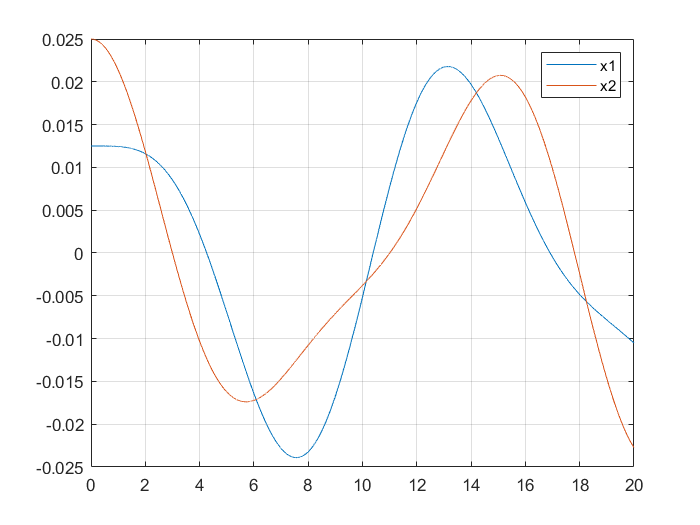

plot(t,x);
grid on;
legend('x1','x2');

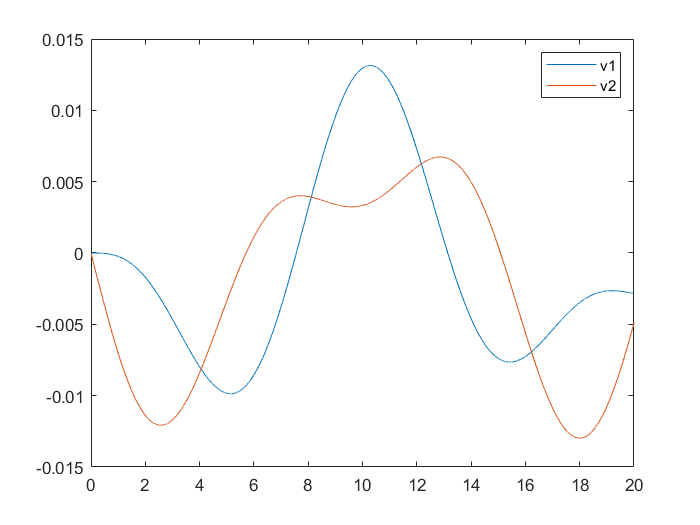

plot(t,v);
legend('v1','v2');

lambda=eig(M)

lambda =    -0.6000
   -0.2000


a=sqrt(lambda)

a =    0.0000 + 0.7746i
   0.0000 + 0.4472i


w=imag(a)

w =     0.7746
    0.4472


periodo=(2*pi)./w

periodo =     8.1116
   14.0496
